UE03(0.5);

IBP(1,1);

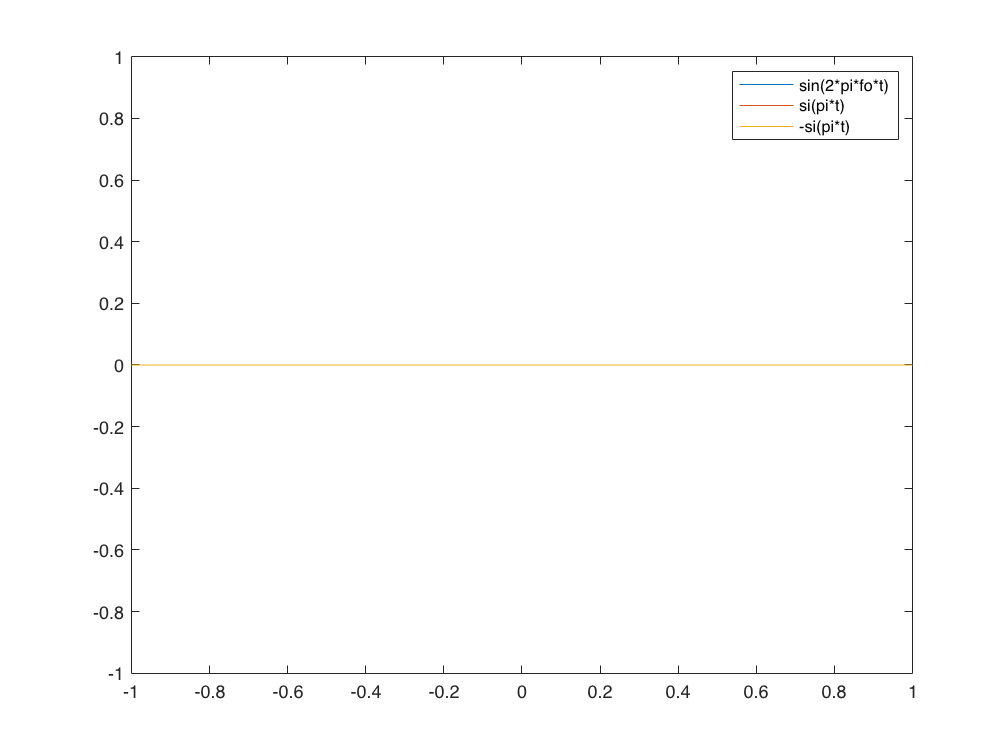

UE03a(1);

function UE03(t)
fo = 10;

t = linspace(-t,t);
y = -sinc(pi*t);
z = sin(2*pi*fo*t);
e = y.*z;

plot(t,e); hold on
plot(t,y);
plot(t,-y);
legend('sin(2*pi*fo*t)','si(pi*t)','-si(pi*t)')
hold off
end

function UE03a(f)
fo = 10;

f = linspace(-f,f);
y = 1i/2*rectangularPulse(f - fo);
z = 1i/2*rectangularPulse(f + fo);
e = y + z;

plot(f,e); hold on
plot(f,y);
plot(f,-y);
legend('sin(2*pi*fo*t)','si(pi*t)','-si(pi*t)')
hold off
end

function IBP(t,fd)
fo = 10;
t = linspace(-t,t);
y = fd*sinc(pi*t*fd);
z = 2*cos(2*pi*fo*t);
e = y.*z;

plot(t,e); hold on
plot(t,y);
plot(t,-y);
legend('sin(2*pi*fo*t)','si(pi*t)','-si(pi*t)')
hold off
end